# **Matlab案例代码解析**

## 2. 典型绘图案例

### 2.3 三维绘图

#### 2.3.7 绘制伪彩图和投影图

颜值即正义；

**颜色模板参考：**[**60套优雅的颜色模板**](https://zhuanlan.zhihu.com/p/444970597)  [**自定义colormap**](https://zhuanlan.zhihu.com/p/489920741)

绘图布局：subplot 和 tiledlayout 

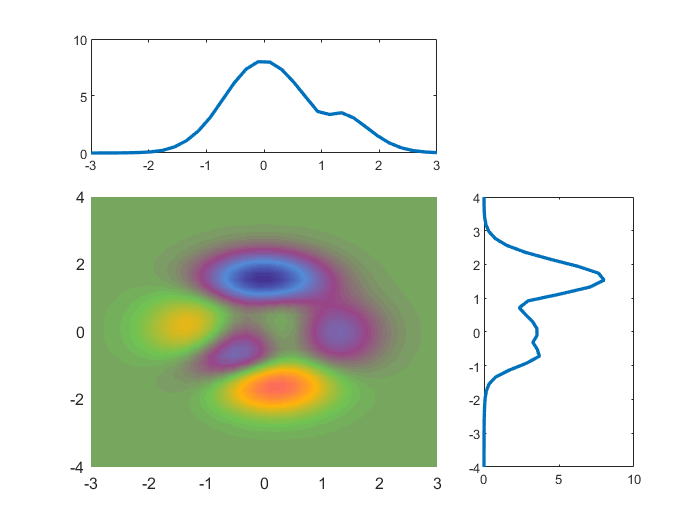

clear;clc;close all;
% 获取到颜色
[all_themes, all_colors] = GetColors(); 
% 创建一个 colormap
map = GenColormap(all_themes{1}, 64);
x = linspace(-3, 3, 30);
y = linspace(-4, 4, 40);
[X, Y] = meshgrid(x, y);
Z = peaks(X, Y);
z1 = max(Z);
z2 = max(Z, [], 2);
figure;
subplot(3, 3, [1, 2]);
plot(x, z1, 'LineWidth', 2);
subplot(3, 3, [6, 9]);
plot(z2, y, 'LineWidth', 2);
subplot(3, 3, [4, 5, 7, 8]);
surf(x, y, Z);
colormap(map);
xlim([-3, 3]);
ylim([-4, 4]);
view(0, 90);
shading interp

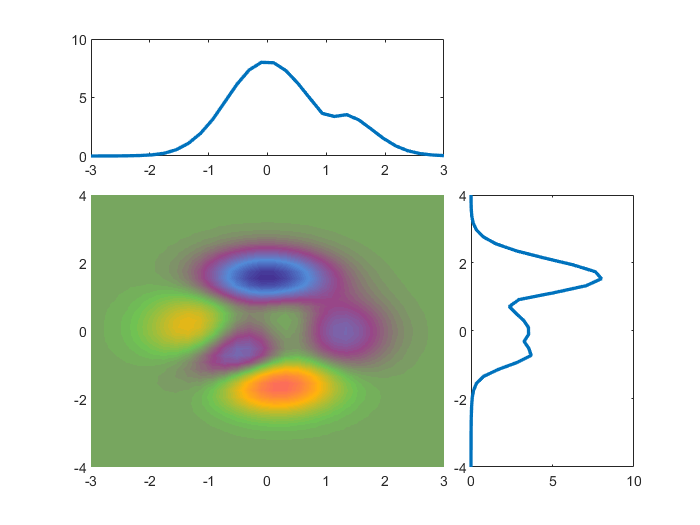

figure;
% 3*3 布局
tiledlayout(3, 3, 'TileSpacing', 'Compact');
% 占据 1*2，也就是 1 2
nexttile([1, 2]);
plot(x, z1, 'LineWidth', 2);
% 从第 6 个开始，占据 2*1，也就是 6 和 9
nexttile(6, [2, 1]);
plot(z2, y, 'LineWidth', 2);
% 从第 4 个开始，占据 2*2，也就是 4 5 7 8
nexttile(4, [2, 2]);
surf(x, y, Z);
colormap(map);
xlim([-3, 3]);
ylim([-4, 4]);
view(0, 90);
shading interp